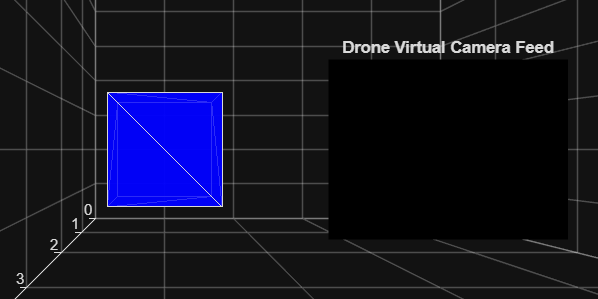

%% -------------------- UAV Simulation with Manual Selection --------------------
clc; clear; close all;

%% -------------------- PARAMETERS --------------------
dt = 0.05; simTime = 20; steps = simTime/dt;

dronePos = [0 0 5];
targets = [5 5 0; 2 6 0; 6 2 0];
targetSize = 0.5;

Kp = 0.5; Ki = 0.01; Kd = 0.1;
prevError = [0 0]; integral = [0 0];

imgWidth = 640; imgHeight = 480;
fov = 60;

%% -------------------- YOLOv4 Detector --------------------
yoloNet = yolov4ObjectDetector('csp-darknet53-coco');

%% -------------------- 3D SCENE --------------------
fig = figure('Name','Drone Simulation','NumberTitle','off','Position',[100 100 1200 600]);

ax3D = axes('Parent',fig,'Position',[0.05 0.1 0.45 0.8]);
hold(ax3D,'on'); grid(ax3D,'on'); axis(ax3D,'equal');
xlabel(ax3D,'X'); ylabel(ax3D,'Y'); zlabel(ax3D,'Z');
xlim(ax3D,[-2 8]); ylim(ax3D,[-2 8]); zlim(ax3D,[0 8]);
title(ax3D,'3D Scene');

[dx,dy,dz] = deal(0.5,0.5,0.2);
hDrone = drawBox(ax3D, dronePos, dx, dy, dz, [0 0 1]);

hTargets = gobjects(size(targets,1),1);
for i = 1:size(targets,1)
    hTargets(i) = drawSphere(ax3D, targets(i,:), targetSize, [1 0 0]);
end

axCam = axes('Parent',fig,'Position',[0.55 0.1 0.4 0.8]);
hCam = imshow(zeros(imgHeight,imgWidth,3,'uint8'),'Parent',axCam);
title(axCam,'Drone Virtual Camera Feed');

%% -------------------- MANUAL SELECTION --------------------
% Capture first frame
camproj(ax3D,'perspective'); 
campos(ax3D, dronePos + [0 0 1]); 
camtarget(ax3D, dronePos + [0 0 -1]);
camup(ax3D,[0 1 0]); camva(ax3D,fov);

drawnow;
frame = frame2im(getframe(ax3D));

Error using matlab.graphics.primitive.canvas.HTMLCanvas/requestCData
Unable to communicate with figure

Error in alternateGetframe

Error in alternateGetframe

Error in alternateGetframe

Error in getframe (line 72)
    x = alternateGetframe(parentFig, offsetRect, scaledOffsetRect, includeDecorations, true, h, offsetRectSpecified);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

camFrame = imresize(frame,[imgHeight imgWidth]);

% Detect objects
[bboxes,scores,labels] = detect(yoloNet, camFrame);

% Draw bounding boxes
camFrameVis = camFrame;
for k = 1:size(bboxes,1)
    camFrameVis = insertShape(camFrameVis,'Rectangle',bboxes(k,:),'Color','yellow','LineWidth',2);
end
set(hCam,'CData',camFrameVis);
drawnow;

% Ask user to click inside the box to select target
title(axCam,'Click inside the object you want to track');
[xClick,yClick] = ginput(1);
%%
% Find the closest bounding box center to the click
dist = zeros(size(bboxes,1),1);
for k = 1:size(bboxes,1)
    cx = bboxes(k,1)+bboxes(k,3)/2;
    cy = bboxes(k,2)+bboxes(k,4)/2;
    dist(k) = sqrt((cx-xClick)^2 + (cy-yClick)^2);
end
[~,targetIdx] = min(dist);

%% -------------------- SIMULATION LOOP --------------------
for tStep = 1:steps
    % Camera setup (downward-looking)
q    camproj(ax3D,'perspective');
    campos(ax3D, dronePos + [0 0 1]); 
    camtarget(ax3D, dronePos + [0 0 -1]);
    camup(ax3D,[0 1 0]); camva(ax3D,fov);

    drawnow;
    frame = frame2im(getframe(ax3D));
    camFrame = imresize(frame,[imgHeight imgWidth]);

    % YOLO detection
    [bboxes,scores,labels] = detect(yoloNet, camFrame);

    % Pick only the selected target
    if ~isempty(bboxes)
        bbox = bboxes(targetIdx,:);
        obj_cx = bbox(1)+bbox(3)/2;
        obj_cy = bbox(2)+bbox(4)/2;

        offsetX = (obj_cx - imgWidth/2) * dronePos(3)/imgHeight;
        offsetY = (obj_cy - imgHeight/2) * dronePos(3)/imgHeight;
    else
        offsetX = 0; offsetY = 0;
    end

    % PID
    error = [offsetX; offsetY];
    integral = integral + error*dt;
    derivative = (error - prevError)/dt;
    pidOut = Kp*error + Ki*integral + Kd*derivative;
    prevError = error;

    dronePos = dronePos + [pidOut(1), pidOut(2), -0.05]*dt;
    updateBox(hDrone, dronePos, dx, dy, dz);

    % Draw camera feed
    camFrameVis = camFrame;
    for k = 1:size(bboxes,1)
        camFrameVis = insertShape(camFrameVis,'Rectangle',bboxes(k,:),'Color','yellow','LineWidth',2);
    end
    % Highlight selected target in green
    camFrameVis = insertShape(camFrameVis,'Rectangle',bboxes(targetIdx,:),'Color','green','LineWidth',3);
    set(hCam,'CData',camFrameVis);

    drawnow;
end

%% -------------------- HELPER FUNCTIONS --------------------
function h = drawBox(ax,pos,dx,dy,dz,color)
    [X,Y,Z] = ndgrid([-dx dx]/2,[-dy dy]/2,[-dz dz]/2);
    X = X(:); Y = Y(:); Z = Z(:);
    k = convhull(X,Y,Z);
    h = patch(ax,'Vertices',[X Y Z]+pos,'Faces',k,'FaceColor',color,'FaceAlpha',0.8);
end

function updateBox(h,pos,dx,dy,dz)
    [X,Y,Z] = ndgrid([-dx dx]/2,[-dy dy]/2,[-dz dz]/2);
    X = X(:); Y = Y(:); Z = Z(:);
    h.Vertices = [X Y Z]+pos;
end

function h = drawSphere(ax,center,radius,color)
    [X,Y,Z] = sphere(20);
    X = X*radius + center(1);
    Y = Y*radius + center(2);
    Z = Z*radius + center(3);
    h = surf(ax,X,Y,Z,'FaceColor',color,'EdgeColor','none','FaceAlpha',1);
end
